# **Project 6 - Exotic and Path Dependent Options, JumpDiffusion Processes **  

warning('off','all')
warning

### **1. **Consider a 12-month **Fixed Strike Lookback Call and Put **options, when the interest rate is 3% per annum, the current stock price is $98 and the strike price is $100. Use the Monte Carlo simulation method to estimate the prices of Call and Put options for the following range of volatilities: from 12% to 48%, in increments of 4%.

The payoff of the Call option is ${\left(S_{\max } -X\right)}^+$, where $S_{\max } =\max \left\lbrace S_t :t\in \left\lbrack 0,T\right\rbrack \right\rbrace$, and the payoff of the Put option is: ${\left(X-S_{\min } \right)}^+$, where $S_{\min }$=$\min \left\lbrace S_t :t\in \left\lbrack 0,T\right\rbrack \right\rbrace \ldotp$

**Inputs**: $S_0$, X, *T, r, *𝜎,* N*

**Outputs**: Graphs: Call and Put options prices as a function of the volatility. Place the Call graph in Proj6_1a.jpg and the Put graph in Proj6_1b.jpg.

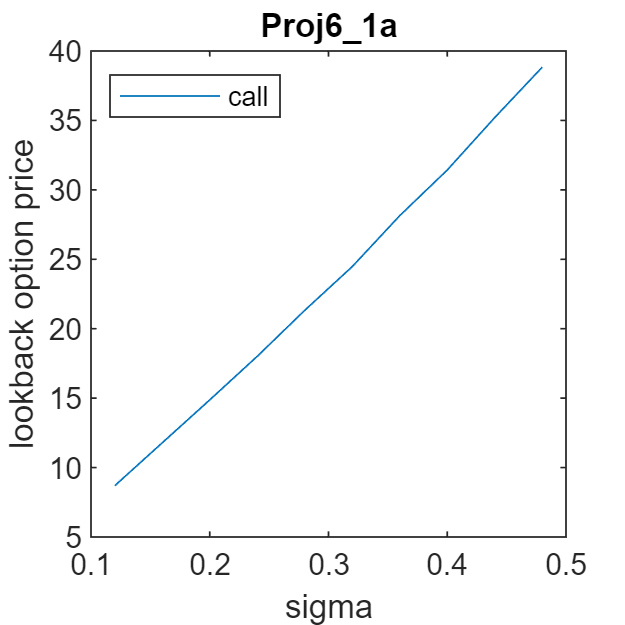

r=0.03; S0=98; X=100; sigma_vec = (12:4:48)/100; T=1; N=10000;
dt=0.01;

fast_fun = @(sigma) lookback_option(S0,r,X,sigma,T,N,dt);
[call,put] = arrayfun(@(sigma_i) fast_fun(sigma_i), sigma_vec);

% plot for call option
plot(sigma_vec,call)
set(gcf,'Position',[250 250 250 250])
legend("call",...
    'Location','northwest','NumColumns',1)
ylabel("lookback option price")
xlabel("sigma")
title("Proj6\_1a")

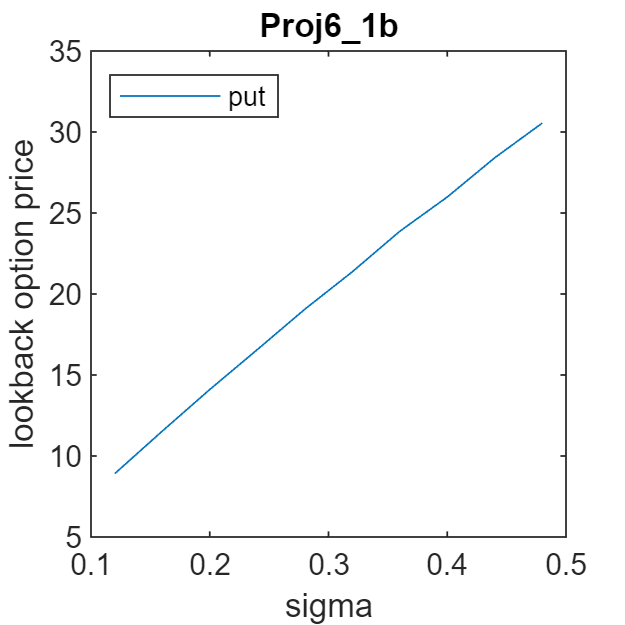

% plot for put option
plot(sigma_vec,put)
set(gcf,'Position',[250 250 250 250])
legend("put",...
    'Location','northwest','NumColumns',1)
ylabel("lookback option price")
xlabel("sigma")
title("Proj6\_1b")

### **2. **Assume that the value of a collateral follows a jump-diffusion process:

$\frac{dV_t }{V_t^- }=\mu \textrm{dt}+\sigma dW_t +\gamma dJ_t$, where $\mu$, $\sigma$,$\gamma$< 0, and $V_0$ are given, J is a Poisson process, with intensity $\lambda_1$, independent of the Brownian Motion process W.

$V_t^-$ is the value process before jump occurs at time t (if any).

Consider a collateralized loan, with a contract rate per period *r *and maturity *T *on the above-collateral, and assume the outstanding balance of that loan follows this process:

$L_t \;=\;a-bc^{12t}$, where a > 0, b > 0, c > 1, and $L_0$ are given. We have that $L_T =0$.

Define the following stopping time:

$Q$=$\min \left\lbrace t\ge 0:V_t \in q_t L_t \right\rbrace$

This stopping time is the first time when the relative value of the collateral (with respect to the outstanding loan balance) crosses a threshold which will be viewed as the “optimal exercise boundary” of the option to default.

Define another stopping time, which is the first time an adverse event occurs: 

$S$=$\min \left\lbrace t\ge 0:N_t >0\right\rbrace$

Assume that 𝑁𝑡 is a Poisson process with intensity of $\lambda_2$.

Define $\tau =\min \left\lbrace Q,S\right\rbrace \ldotp$

We assume the embedded default option will be exercised at time $\tau$, if and only if $\tau <T$.

If the option is exercised at time Q then the payoff to the borrower is:${\left(L_Q -{\epsilon V}_Q \right)}^+$.

If the option is exercised at time S then the payoff to the borrower is: abs($L_Q -{\epsilon V}_Q$), where *abs(.) *is the absolute value function.

**Notes:**

-  If $\min \left\lbrace Q,S\right\rbrace >T,$ then there is no default option exercise.

- $\epsilon$ Should be viewed as the recovery rate of the collateral, so (1-$\epsilon$) can be viewed as the legal and administrative expenses.

Assume *J *has intensity $\lambda_1$ and *N *has intensity $\lambda_2$. *N *is independent of *J *and *W*.

Assume the APR of the loan is $R=r_0 +{\delta \lambda }_2$, where $r_0$ is the “risk-free” rate, and $\delta$ is a positive parameter to measure the borrower’s creditworthiness in determining the contract rate per period: *r.*

We have monthly compounding here, so r = $R$/12.

Assume that $q_t =\alpha +\beta t$, where $\beta$ > 0, $\alpha$ < $V_0$/$L_0$ and $\beta$ = $\frac{\varepsilon -\alpha }{T}$.

Use $r_0$ for discounting cash flows. Use the following base-case parameter values:

$V_0$ = $20,000, $L_0$ = $22,000, $\mu$= -0.1, $\sigma$ = 0.2, $\gamma$= -0.4, $\lambda_1$ = 0.2, T = 5 years, $r_0$ = 0.02, 𝛿 = 0.25, $\lambda_2$ = 0.4, $\alpha$ = 0.7, $\varepsilon$ = 0.95. Notice that, PMT= $\;\frac{L_0 \;r}{\left\lbrack 1-\frac{1}{{\left(1+r\right)}^n }\right\rbrack }$, where r = R/12, n = T*12, and $a=\frac{\textrm{PMT}}{r}$ , $b=\frac{\textrm{PMT}}{r{\left(1+r\right)}^n }$, $c=\left(1+r\right)$. Notice that, $q_T$= $\varepsilon$.

Write the code as a function Proj6_2func.* that takes $\lambda_1$*, *$\lambda_2$ and *T *as parameters, setting defaults if these parameters are not supplied, and outputs the default option price, the default probability and the expected exercise time. Function specification:

function [D, Prob, Et] = Proj6_2func(lambda1, lambda2, T)

**(a)** Estimate the value of the default option for the following ranges of parameters:

    $\lambda_1$ from 0.05 to 0.4 in increments of 0.05;

    $\lambda_2$ from 0.0 to 0.8 in increments of 0.1;

    T from 3 to 8 in increments of 1;

**(b)** Estimate default probability for the following ranges of parameters:.

    $\lambda_1$ from 0.05 to 0.4 in increments of 0.05;

    $\lambda_2$ from 0.0 to 0.8 in increments of 0.1;

    T from 3 to 8 in increments of 1;

**(c)** Find the Expected Exercise Time of the default option, conditional on $\tau$ < T. That is, estimate $E\left(\left.\tau \;|<T\right)\right)$  for the following ranges of parameters:.

    $\lambda_1$ from 0.05 to 0.4 in increments of 0.05;

    $\lambda_2$ from 0.0 to 0.8 in increments of 0.1;

    T from 3 to 8 in increments of 1;

**Inputs**: s*eed*

**Outputs**:

i. Values: the default option D, the default probability Prob and the expected exercise time $E_t$ for parts (a), (b) and (c) with $\lambda_1$=0.2, $\lambda_2$=0.4 and T=5.

ii. Graphs: For each of (a), (b) and (c) two graphs as a function of T, first with $\lambda_1$=0.2 and $\lambda_2$ from 0.0 to 0.8 in increments of 0.1, then with $\lambda_2$ = 0.4 and $\lambda_1$ from 0.05 to 0.4 in increments of 0.05. Put the two graphs in one .png file.

% run codes to get option valye, default probability Prob and the expected
% exercise time
lambda1_vec = 0.05:0.05:0.4;
lambda2_vec = 0:0.1:0.8;
T_vec = 3:8;

option_price = zeros(5,8,9);
default_prob = zeros(5,8,9);
exp_ex_time = zeros(5,8,9);
for i = 1:6
    for j = 1:8
        T = T_vec(i);
        l1 = lambda1_vec(j);
        fast_l2 = @(l2) Proj6_2func(l1,l2,T);
        [option_price(i,j,:), default_prob(i,j,:), exp_ex_time(i,j,:)] = arrayfun(@(l2) fast_l2(l2), lambda2_vec);
    end
end

**(a)** Plots

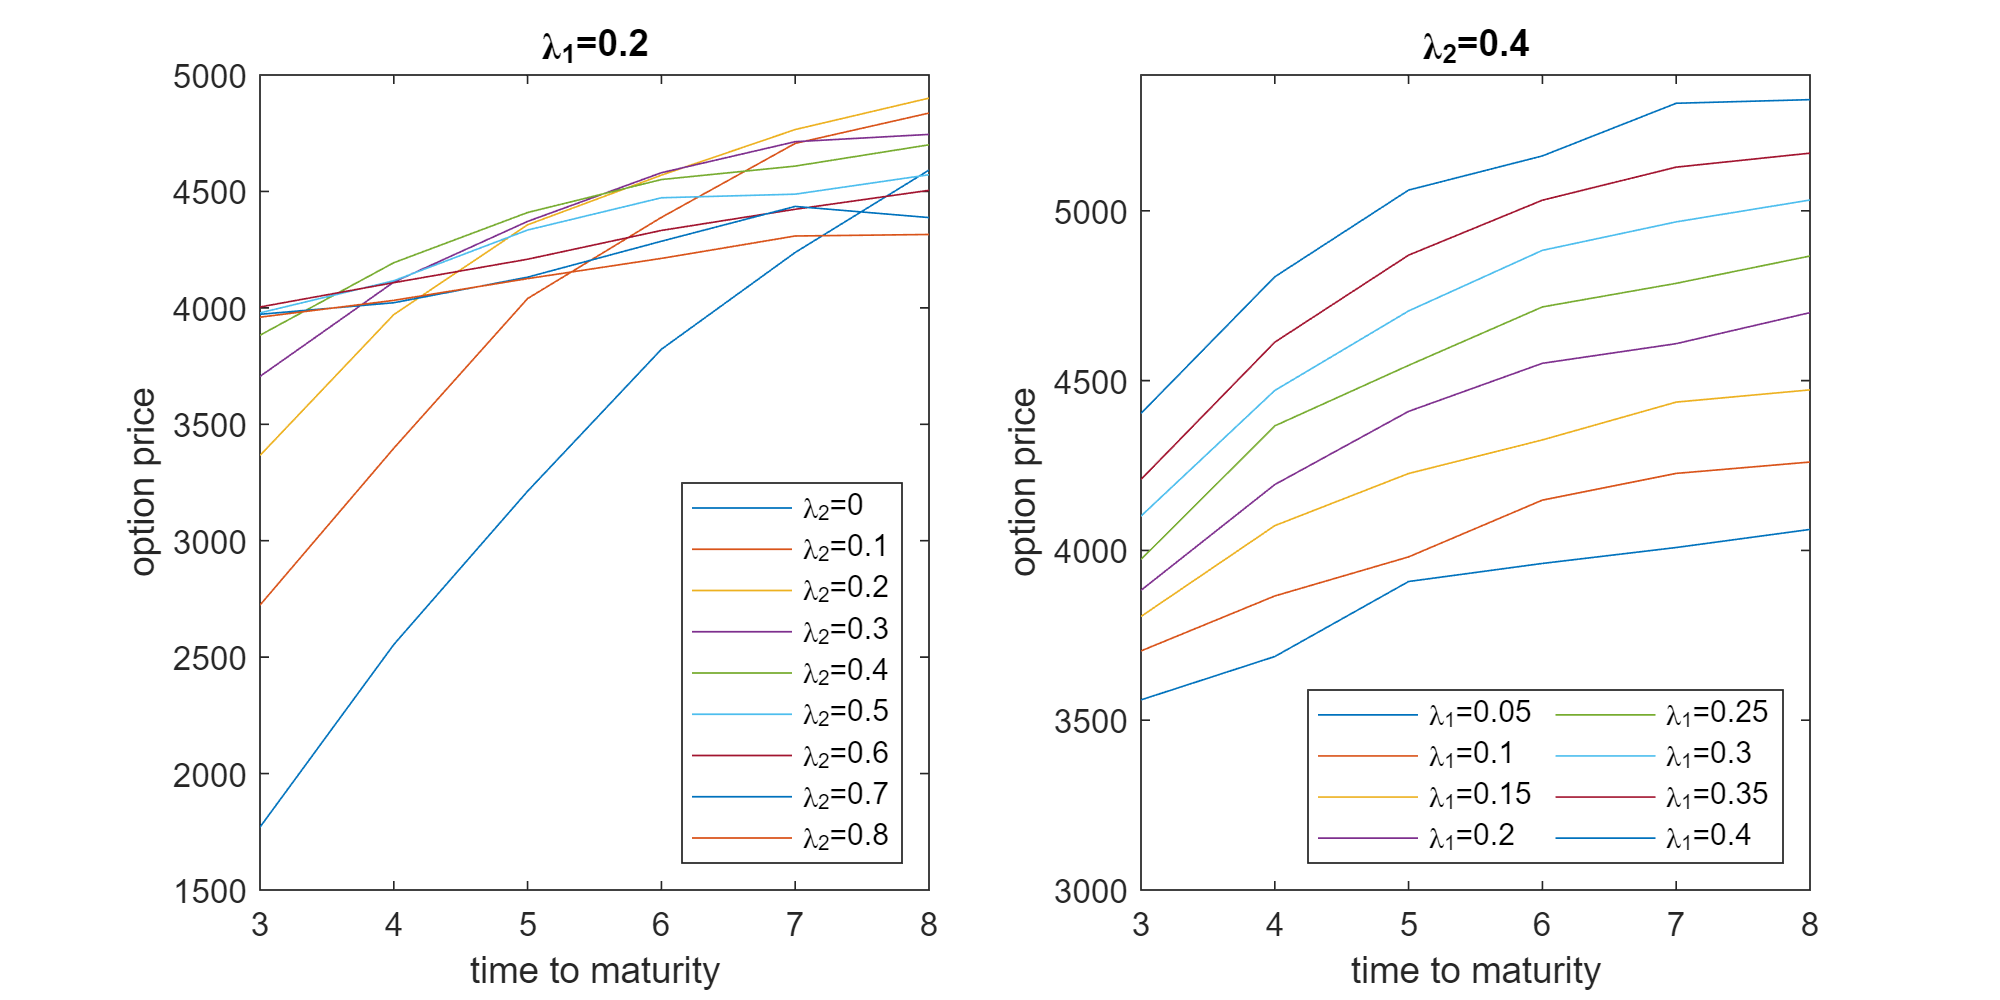

legend_vec = strings(9,1);
figure;
subplot(1,2,1);
for k = 1:9 
    l2=lambda2_vec(k);
    legend_vec(k) = append("\lambda_2=",string(l2));
    plot(T_vec,option_price(:,4,k))
    hold on
end
hold off

set(gcf,'Position',[400 400 800 400])
legend(legend_vec,...
    'Location','southeast','NumColumns',1)
ylabel("option price")
xlabel("time to maturity")
title("\lambda_1=0.2")

subplot(1,2,2);
legend_vec2 = strings(8,1);
for k = 1:8 
    l1=lambda1_vec(k);
    legend_vec2(k) = append("\lambda_1=",string(l1));
    plot(T_vec,option_price(:,k,5))
    hold on
end
hold off

set(gcf,'Position',[400 400 800 400])
legend(legend_vec2,...
    'Location','southeast','NumColumns',2)
ylabel("option price")
ylim([3000 5400])
xlabel("time to maturity")
title("\lambda_2=0.4")

**(b)** Plots

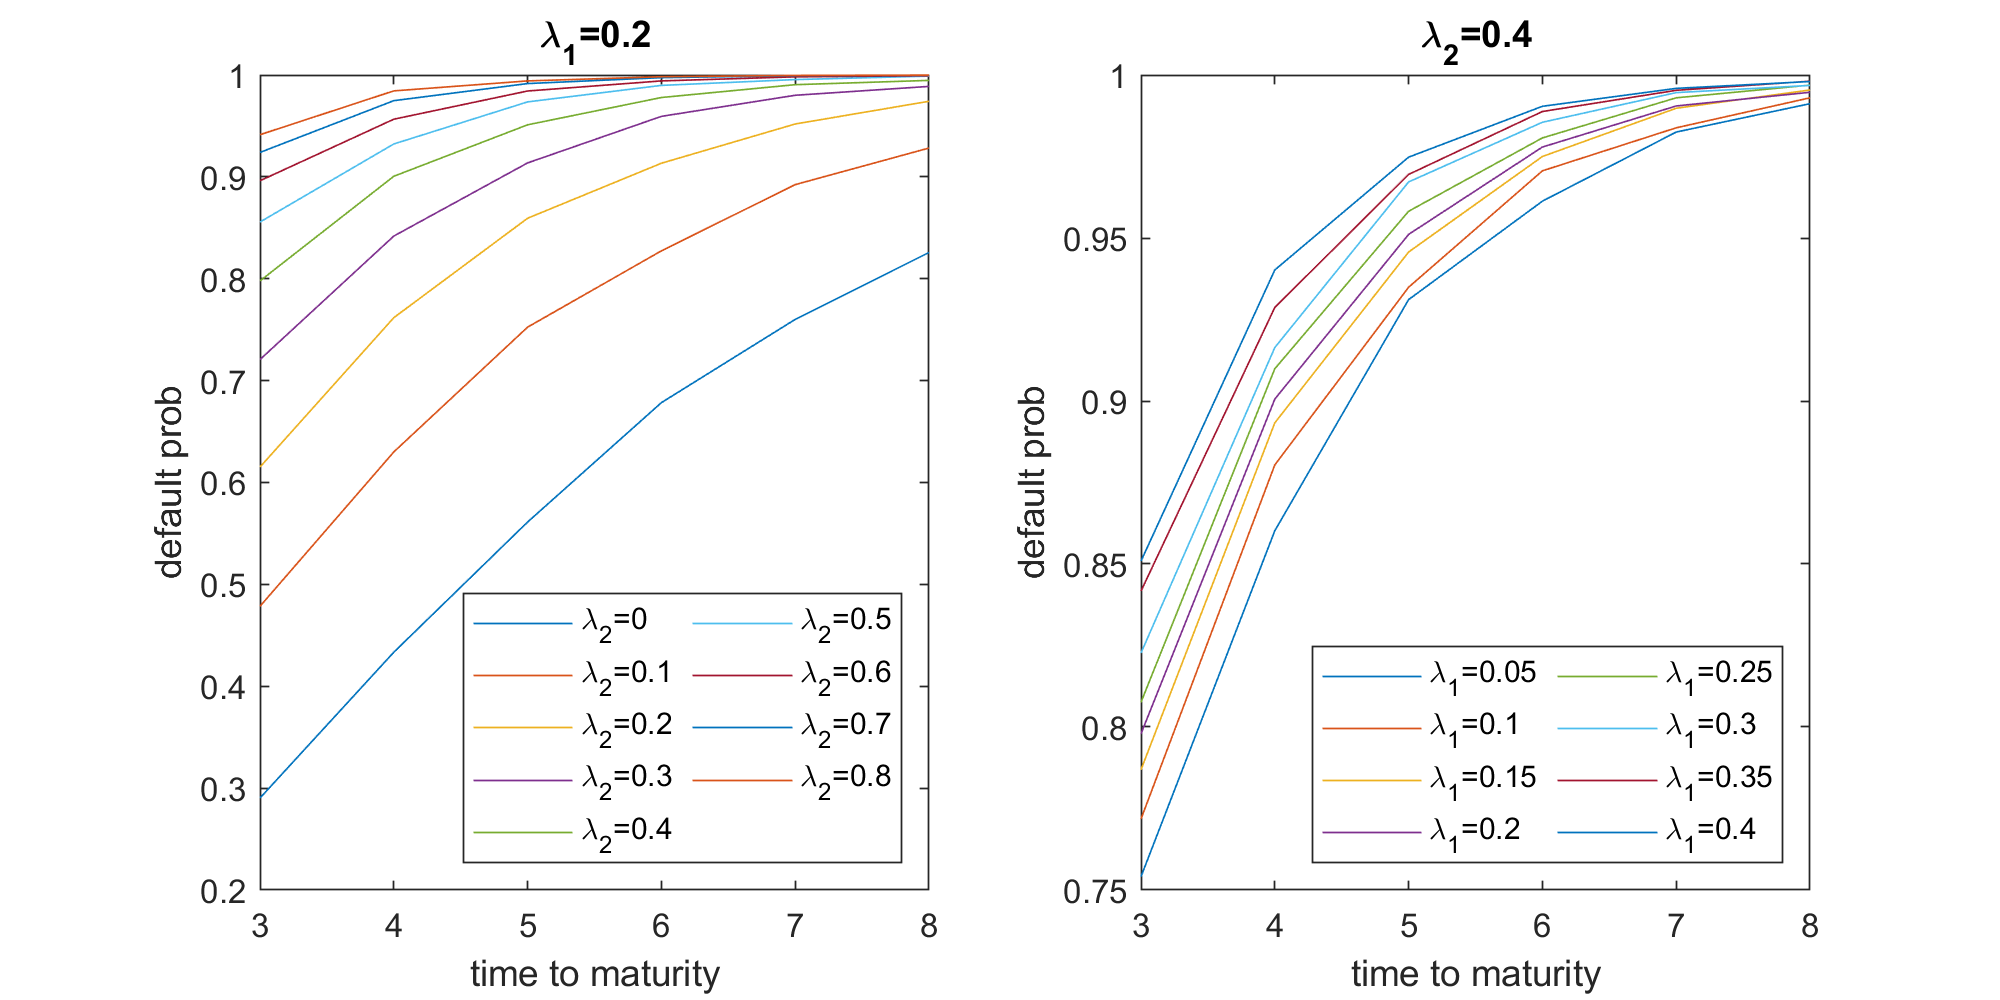

figure;
subplot(1,2,1);
legend_vec = strings(9,1);
for k = 1:9 
    l2=lambda2_vec(k);
    legend_vec(k) = append("\lambda_2=",string(l2));
    plot(T_vec,default_prob(:,4,k))
    hold on
end
hold off

set(gcf,'Position',[400 400 800 400])
legend(legend_vec,...
    'Location','southeast','NumColumns',2)
ylabel("default prob")
xlabel("time to maturity")
title("\lambda_1=0.2")

subplot(1,2,2);
legend_vec2 = strings(8,1);
for k = 1:8 
    l1=lambda1_vec(k);
    legend_vec2(k) = append("\lambda_1=",string(l1));
    plot(T_vec,default_prob(:,k,5))
    hold on
end
hold off

set(gcf,'Position',[400 400 800 400])
legend(legend_vec2,...
    'Location','southeast','NumColumns',2)
ylabel("default prob")
xlabel("time to maturity")
title("\lambda_2=0.4")

**(c)** Plots

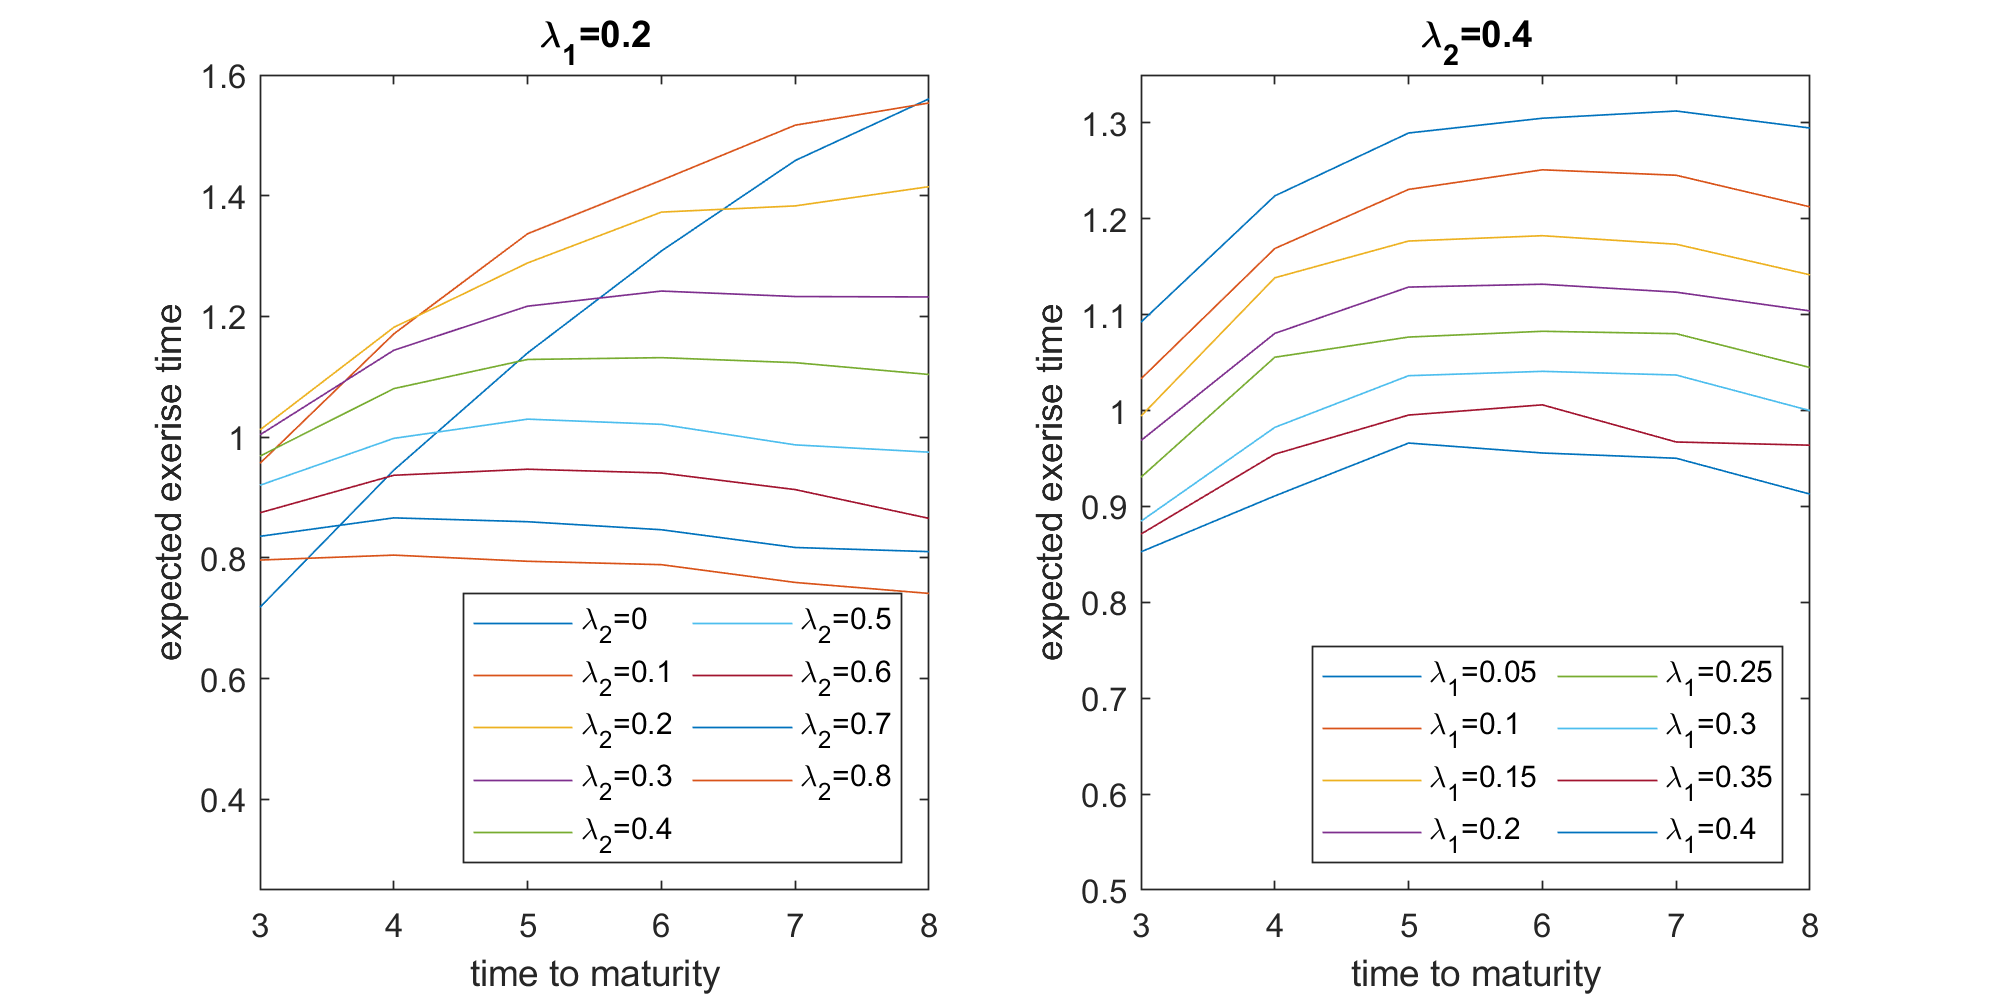

figure;
subplot(1,2,1);
legend_vec = strings(9,1);
for k = 1:9 
    l2=lambda2_vec(k);
    legend_vec(k) = append("\lambda_2=",string(l2));
    plot(T_vec,exp_ex_time(:,4,k))
    hold on
end
hold off

set(gcf,'Position',[400 400 800 400])
legend(legend_vec,...
    'Location','southeast','NumColumns',2)
ylabel("expected exerise time")
ylim([0.25 1.6])
xlabel("time to maturity")
title("\lambda_1=0.2")

subplot(1,2,2);
legend_vec2 = strings(8,1);
for k = 1:8 
    l1=lambda1_vec(k);
    legend_vec2(k) = append("\lambda_1=",string(l1));
    plot(T_vec,exp_ex_time(:,k,5))
    hold on
end
hold off

set(gcf,'Position',[400 400 800 400])
legend(legend_vec2,...
    'Location','southeast','NumColumns',2)
ylabel("expected exerise time")
ylim([0.5 1.35])
xlabel("time to maturity")
title("\lambda_2=0.4")

function [call,put] = lookback_option(S0,r,X,sigma,T,N,dt)
    step = ceil(T/dt);
    St = zeros(N,step+1); St(:,1)=S0;
    for i = 2:(step+1)
        Wt = normrnd(0,sqrt(dt),[1,N/2]);
        St(:,i) = St(:,i-1) + r* St(:,i-1)*dt + sigma*St(:,i-1).*[Wt, -Wt]';
    end
    call_payoff = max(max(St,[],2)-X,0);
    put_payoff = max(X-min(St,[],2),0);
    call = mean(exp(-r*T)*call_payoff,1);
    put = mean(exp(-r*T)*put_payoff,1);
end

function result = find_0(vec,axis)
    result = find(vec,axis);
    [row,col] = size(result);
    if row*col==0
        % assign Inf if the set is empty
        result = Inf; 
    end
end

function value = get_Vt(Vt, tao, ttime)
% helper function
    if isinf(tao(ttime))
        value = nan;
    else
        value = Vt(ttime,tao(ttime)+1); % +1 is to modify for the position
    end
end

function [D, Prob, Et] = Proj6_2func(lambda1, lambda2, T)
    V0 = 20000;L0=22000; N=10000;
    mu=-0.1;sigma=0.2;gamma=-0.4;
    r0=0.02; delta = 0.25; alpha=0.7; 
    epsilon=0.95; % recovery rate of the collateral
    R = r0+delta*lambda2;
    r=R/12; beta = (epsilon-alpha)/T;
    % q_T = epsilon;
    n=T*12; PMT = L0*r/(1-1/((1+r)^n));
    a = PMT/r; b=PMT/(r*(1+r)^n); c=1+r;
    
    dt = 0.01;
    step = T/dt;

    Nt = poissrnd(lambda2*dt,N,step);
    fast_find = @(try_time) find_0(Nt(try_time,:)>0,1);
    S = arrayfun(@(try_time) fast_find(try_time),1:N);
    

    Vt = zeros(N,step+1); Vt(:,1) = V0; 
    q0 = alpha;
    qLt = zeros(1,step+1); qLt(1) = q0*L0; 
    J = poissrnd(lambda1*dt,N,step);
    for i = 2:(step+1)
        Wt = normrnd(0,sqrt(dt),[1,N/2]);
        t = dt*i-dt;
        Lt = a-b*c^(12*t);
        q_t = alpha+beta*t; % beta>0, alpha<V0/L0
        qLt(i) = q_t*Lt;
        Vt(:,i) = Vt(:,i-1) + Vt(:,i-1)*mu*dt + sigma*Vt(:,i-1).*[Wt, -Wt]' + gamma * J(:,i-1).* Vt(:,i-1);
    end
    
    fast_find2 = @(try_time) find_0(qLt>=Vt(try_time,:),1)-1;
    Q = arrayfun(@(ttime) fast_find2(ttime),1:N);
    tao = min(Q,S);
    
    %Prob = mean(mean((qLt(2:(step+1))>=Vt(2:(step+1)))|(Nt>0),2),1);
    Prob = mean(~isinf(tao),2);

    if isinf(tao)
        D = 0;
        Et = Inf; % or inf?
    else
        inf_flag = isinf(tao);
        type_flag = (tao==Q); % 1 if type is Q; o.w. type is S or inf
        Lt = a-b*c.^(12.*(tao.*dt)); Lt(inf_flag) = nan;

        fast_get = @(ttime) get_Vt(Vt, tao, ttime);
        V_qs = arrayfun(@(ttime) fast_get(ttime),1:N);
        Q_value = (type_flag & (~inf_flag)).*max(Lt-epsilon.*V_qs,0);
        Q_value(isnan(Q_value))=0;
        S_value = ((~type_flag) & (~inf_flag)).*abs(Lt-epsilon.*V_qs);
        S_value(isnan(S_value))=0;
        option = Q_value + S_value;
        option(inf_flag) = 0;
        D = mean(option,2)*exp(-r0*T);
        Et = mean(tao(~inf_flag).*dt,2);
    end
end